% Parametry stałe
T_total = 5000000; % ms
frequency_of_incoming_packet = 12000; % ms
packet_reception_time = 10; % ms

% Wykres 1: Zmienny inactivity timer
longDRX_cycle = 10240; % ms (stałe)
on_duration = 100; % ms (stałe)
inactivity_timers = [0, 1, 2, 3, 4, 5, 6, 8, 10, 20, 30, 40, 50, 60, 80, 100, 200, 300, 500, 750, 1280, 1920, 2560]; % ms (zmienne)

energy_gains1 = zeros(size(inactivity_timers));
mean_delays1 = zeros(size(inactivity_timers));

for i = 1:length(inactivity_timers)
    [energy_gains1(i), mean_delays1(i)] = drx_script(...
        T_total, longDRX_cycle, inactivity_timers(i), on_duration, ...
        frequency_of_incoming_packet, packet_reception_time);
end


=== Starting DRX Simulation ===
Total simulation time: 5000000 ms
Long DRX cycle: 10240 ms
Inactivity timer: 0 ms
On duration: 100 ms
Packet frequency: 12000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 0 ms (Energy: 0.0 mJ)
! STATE ON time counter: 0)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 10240 ms (Energy: 10479.3 mJ)
[Energy update] Total: 10479.3 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 100
ON_DURATION: 100 ms (Energy: 10000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 10140 ms (Energy: 10379.3 mJ)
[Energy update] Total: 30858.6 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION

[Packet #2 arrived during SLEEP at last cycle at 12000 ms]

[Processing 1 pending packets that arrived during SLEEP]
-> Processing packet arrived at 12000 ms (delay: 8480 ms)
[Energy after processing 1 packets] Total: 42858.6 mJ | Saved: 0.0%
-> State change: ON_DURATION -> INA

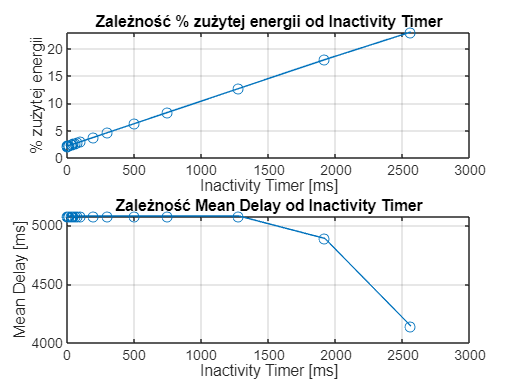


figure;
subplot(2,1,1);
plot(inactivity_timers, energy_gains1, '-o');
title('Zależność % zużytej energii od Inactivity Timer');
xlabel('Inactivity Timer [ms]');
ylabel('% zużytej energii');
grid on;

subplot(2,1,2);
plot(inactivity_timers, mean_delays1, '-o');
title('Zależność Mean Delay od Inactivity Timer');
xlabel('Inactivity Timer [ms]');
ylabel('Mean Delay [ms]');
grid on;

% Wykres 2: Zmienny long DRX cycle

% Parametry stałe
T_total = 250000; % ms
frequency_of_incoming_packet = 12000; % ms
packet_reception_time = 10; % ms

inactivity_timer = 500; % ms (stałe)
longDRX_cycles = [128, 160, 256, 320, 512, 640, 1024, 1280, 2048, 2560, 5120, 10240]; % ms (zmienne)
on_duration = 100; % ms (stałe)

energy_gains2 = zeros(size(longDRX_cycles));
mean_delays2 = zeros(size(longDRX_cycles));

for i = 1:length(longDRX_cycles)
    [energy_gains2(i), mean_delays2(i)] = drx_script(...
        T_total, longDRX_cycles(i), inactivity_timer, on_duration, ...
        frequency_of_incoming_packet, packet_reception_time);
end


=== Starting DRX Simulation ===
Total simulation time: 250000 ms
Long DRX cycle: 128 ms
Inactivity timer: 500 ms
On duration: 100 ms
Packet frequency: 12000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 500 ms (Energy: 50000.0 mJ)
! STATE ON time counter: 500)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 128 ms (Energy: 367.3 mJ)
[Energy update] Total: 50367.3 mJ | Saved: 0.2%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 100
ON_DURATION: 100 ms (Energy: 10000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 28 ms (Energy: 267.3 mJ)
[Energy update] Total: 60634.6 mJ | Saved: 0.2%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 100
ON_DURATION: 100 ms (Energy: 10000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #3)
DEEP_SLEEP: 28 ms (Energy: 267.3 mJ)
[Energy update] Total: 70902.0 mJ | Saved: 0.3%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 100
ON_DURATIO

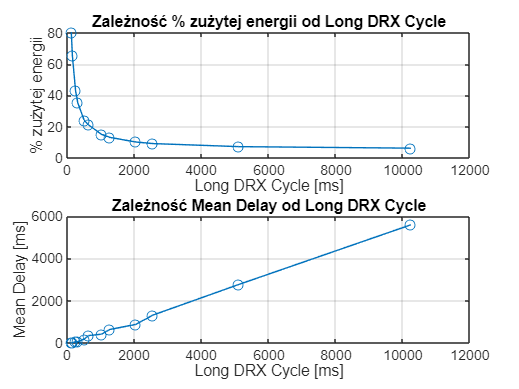


figure;
subplot(2,1,1);
plot(longDRX_cycles, energy_gains2, '-o');
title('Zależność % zużytej energii od Long DRX Cycle');
xlabel('Long DRX Cycle [ms]');
ylabel('% zużytej energii');
grid on;

subplot(2,1,2);
plot(longDRX_cycles, mean_delays2, '-o');
title('Zależność Mean Delay od Long DRX Cycle');
xlabel('Long DRX Cycle [ms]');
ylabel('Mean Delay [ms]');
grid on;

% Wykres 3: Zmienny on duration

% Parametry stałe
T_total = 5000000; % ms
frequency_of_incoming_packet = 12000; % ms
packet_reception_time = 10; % ms

inactivity_timer = 100; % ms (stałe)
longDRX_cycle = 10240; % ms (stałe)
on_durations = [1, 2, 3, 4, 5, 6, 8, 10, 20, 30, 40, 50, 60, 80, 100, 200, 300, 500, 600, 800, 1000, 1200, 1600]; % ms (zmienne)

energy_gains3 = zeros(size(on_durations));
mean_delays3 = zeros(size(on_durations));

for i = 1:length(on_durations)
    [energy_gains3(i), mean_delays3(i)] = drx_script(...
        T_total, longDRX_cycle, inactivity_timer, on_durations(i), ...
        frequency_of_incoming_packet, packet_reception_time);
end


=== Starting DRX Simulation ===
Total simulation time: 5000000 ms
Long DRX cycle: 10240 ms
Inactivity timer: 100 ms
On duration: 1 ms
Packet frequency: 12000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 10140 ms (Energy: 10379.3 mJ)
[Energy update] Total: 20379.3 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 1
ON_DURATION: 1 ms (Energy: 100.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 10239 ms (Energy: 10478.3 mJ)
[Energy update] Total: 30957.6 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION

[Packet #2 arrived during SLEEP at last cycle at 12000 ms]

[Processing 1 pending packets that arrived during SLEEP]
-> Processing packet arrived at 12000 ms (delay: 8480 ms)
! STATE ON time counter: 10)
[Energy after processing 1 packets] Total: 33957.6 mJ | Saved: 0.0%
INAC

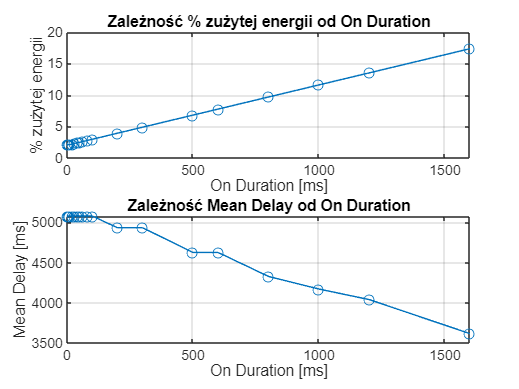


figure;
subplot(2,1,1);
plot(on_durations, energy_gains3, '-o');
title('Zależność % zużytej energii od On Duration');
xlabel('On Duration [ms]');
ylabel('% zużytej energii');
grid on;

subplot(2,1,2);
plot(on_durations, mean_delays3, '-o');
title('Zależność Mean Delay od On Duration');
xlabel('On Duration [ms]');
ylabel('Mean Delay [ms]');
grid on;

% Wykres 4: eDRX zmienny Cycle
% Parametry stałe
T_total = 100000000; % ms
frequency_of_incoming_packet = 15000000; % ms
packet_reception_time = 10; % ms

inactivity_timer = 0; % ms (stałe)
longDRX_cycles = [20480, 40960, 81920, 163840, 327680, 655360, 1310720, 2621440, 5242880, 10485760]; % ms (zmienne)
on_duration = 2560; % ms (stałe)

energy_gains_edrx_1 = zeros(size(longDRX_cycles));
mean_delays_edrx_1 = zeros(size(longDRX_cycles));

for i = 1:length(longDRX_cycles)
    [energy_gains_edrx_1(i), mean_delays_edrx_1(i)] = drx_script(...
        T_total, longDRX_cycles(i), inactivity_timer, on_duration, ...
        frequency_of_incoming_packet, packet_reception_time);
end


=== Starting DRX Simulation ===
Total simulation time: 100000000 ms
Long DRX cycle: 20480 ms
Inactivity timer: 0 ms
On duration: 2560 ms
Packet frequency: 15000000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 0 ms (Energy: 0.0 mJ)
! STATE ON time counter: 0)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 20480 ms (Energy: 20719.3 mJ)
[Energy update] Total: 20719.3 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 2560
ON_DURATION: 2560 ms (Energy: 256000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 17920 ms (Energy: 18159.3 mJ)
[Energy update] Total: 294878.6 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 2560
ON_DURATION: 2560 ms (Energy: 256000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #3)
DEEP_SLEEP: 17920 ms (Energy: 18159.3 mJ)
[Energy update] Total: 569038.0 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time co

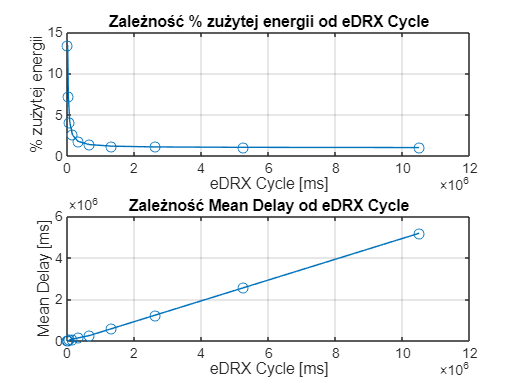


figure;
subplot(2,1,1);
plot(longDRX_cycles, energy_gains_edrx_1, '-o');
title('Zależność % zużytej energii od eDRX Cycle');
xlabel('eDRX Cycle [ms]');
ylabel('% zużytej energii');
grid on;

subplot(2,1,2);
plot(longDRX_cycles, mean_delays_edrx_1, '-o');
title('Zależność Mean Delay od eDRX Cycle');
xlabel('eDRX Cycle [ms]');
ylabel('Mean Delay [ms]');
grid on;

% Wykres 5: eDRX zmienny Paging Time Window 5,46 min eDRX cycle
% Parametry stałe
T_total = 100000000; % ms
frequency_of_incoming_packet = 500000; % ms
packet_reception_time = 10; % ms

inactivity_timer = 0; % ms (stałe)
longDRX_cycle = 327680; % ms (stałe) 5,46 min ok
on_durations = [1280, 2560, 3840, 5120, 6400, 7680, 8960, 10240, 11520, 12800, 14080, 15360, 16640, ...
              17920, 19200, 20480, 21760, 23040, 24320, 25600, 26880, 28160, 29440, 30720, 32000, ...
              33280, 34560, 35840, 37120, 38400, 39680, 40960]; % ms (zmienne)

energy_gains_edrx_2 = zeros(size(longDRX_cycles));
mean_delays_edrx_2 = zeros(size(longDRX_cycles));

for i = 1:length(longDRX_cycles)
    [energy_gains_edrx_2(i), mean_delays_edrx_2(i)] = drx_script(...
        T_total, longDRX_cycle, inactivity_timer, on_durations(i), ...
        frequency_of_incoming_packet, packet_reception_time);
end


=== Starting DRX Simulation ===
Total simulation time: 100000000 ms
Long DRX cycle: 327680 ms
Inactivity timer: 0 ms
On duration: 1280 ms
Packet frequency: 500000 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 0 ms (Energy: 0.0 mJ)
! STATE ON time counter: 0)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 327680 ms (Energy: 327919.3 mJ)
[Energy update] Total: 327919.3 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 1280
ON_DURATION: 1280 ms (Energy: 128000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
DEEP_SLEEP: 326400 ms (Energy: 326639.3 mJ)
[Energy update] Total: 782558.6 mJ | Saved: 0.0%
-> State change: SLEEP -> ON_DURATION

[Packet #2 arrived during SLEEP at last cycle at 500000 ms]

[Processing 1 pending packets that arrived during SLEEP]
-> Processing packet arrived at 500000 ms (delay: 155360 ms)
[Energy after processing 1 packets] Total: 912558.6 mJ | Saved: 0.0%
-> State change:

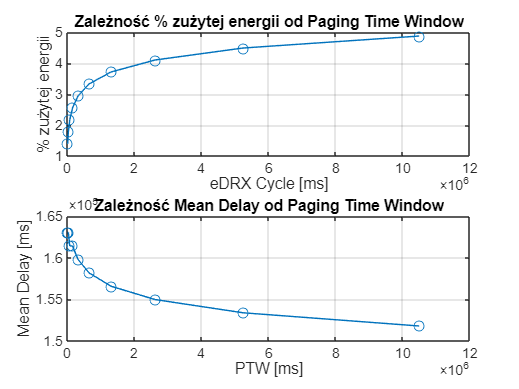


figure;
subplot(2,1,1);
plot(longDRX_cycles, energy_gains_edrx_2, '-o');
title('Zależność % zużytej energii od Paging Time Window');
xlabel('eDRX Cycle [ms]');
ylabel('% zużytej energii');
grid on;

subplot(2,1,2);
plot(longDRX_cycles, mean_delays_edrx_2, '-o');
title('Zależność Mean Delay od Paging Time Window');
xlabel('PTW [ms]');
ylabel('Mean Delay [ms]');
grid on;